Hope you enjoyed Week 1 of the Aerial Robotics course

It's time for the 1st assignment of the course

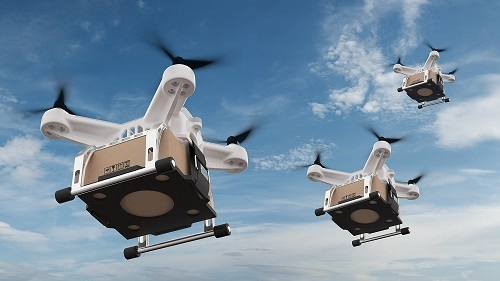

**Swarm robotics** is an approach to the coordination of multiple robots as a system which consist of large numbers of mostly simple physical robots. 

It is supposed that a desired collective behavior emerges from the interactions between the robots and interactions of robots with the environment. 

This approach emerged on the field of artificial swarm intelligence, as well as the biological studies of insects, ants and other fields in nature, where swarm behaviour occurs.

some students from IIT Bombay are making a project on swarm robotics,

they have programmed 3 drones to fly in a fixed direction in such a way that their accelerations follow the following relations

a1 = v1 - v2;

a2 = v3 - 3;

a3 = v1 - v2 - v3 + 3;

They want to perform a maneuver when all drones attain the same velocity but they have no way of measuring the velocity of drones

The maneuver has to start within the first 5 seconds of normal flight (following the given equations)

By now you have the necessary skills and the power of MATLAB to help them in their project.

Plot graphs of speed vs time for all three drones in one graph.

and determine at what point of time should they start the maneuver.

Initial velocity of the drones are 2m/s, 4m/s and -1m/s .


syms v_1(t) v_2(t) v_3(t)

% Writing three differential equations, controlling the velocities of the
% drones
ode1 = diff(v_1) == v_1 - v_2;
ode2 = diff(v_2) == v_3 -3;
ode3 = diff(v_3) == v_1 - v_2 - v_3 +3;
odes = [ode1; ode2; ode3]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}v_{1}\left(t\right)=v_{1}\left(t\right)-v_{2}\left(t\right)\\ \frac{\partial }{\partial t}v_{2}\left(t\right)=v_{3}\left(t\right)-3\\ \frac{\partial }{\partial t}v_{3}\left(t\right)=v_{1}\left(t\right)-v_{2}\left(t\right)-v_{3}\left(t\right)+3 \end{array}\right)$$

% Writing the initial velocities of the drones
cond1 = v_1(0) == 2;
cond2 = v_2(0) == 4;
cond3 = v_3(0) == -1;
conds = [cond1; cond2; cond3];

[v_1Sol(t),v_2Sol(t), v_3Sol(t)] = dsolve(odes,conds)

$$v\_1Sol(t) = \left(3\,t-1\right)\,\left(t+1\right)-t-\frac{3\,t\,\left(t+2\right)}{2}-\frac{t^{2}}{2}+3$$

$$v\_2Sol(t) = t\,\left(3\,t-1\right)-\frac{3\,t\,\left(t+2\right)}{2}-\frac{t^{2}}{2}+4$$

$$v\_3Sol(t) = 2\,t-1$$

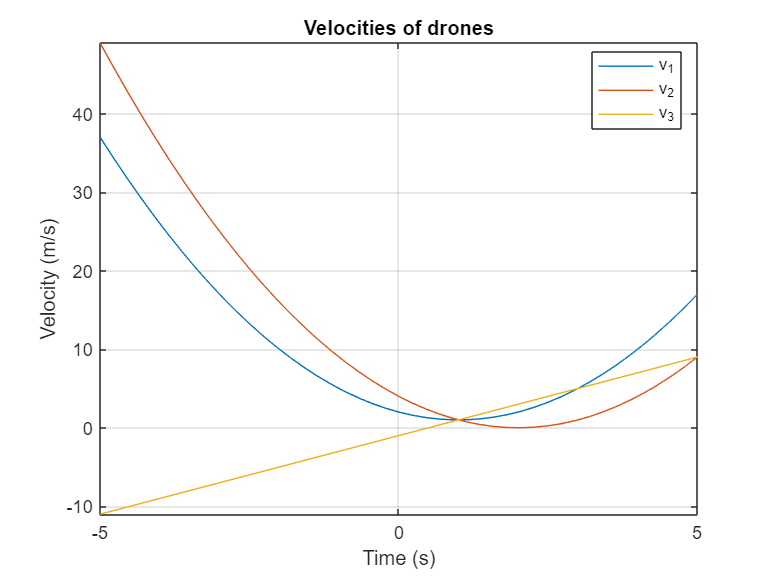

% Plotting the velocities as a function of time
fplot(v_1Sol)
hold on
fplot(v_2Sol)
hold on
fplot(v_3Sol)
grid on
legend('v_1','v_2','v_3','Location','best')
title('Velocities of drones')

ylabel('Velocity (m/s)') 
xlabel('Time (s)') 

% Finding the time at which the velocities of the drones are same

intersection=find(abs(v_1Sol-v_2Sol)<0.0001 & abs(v_2Sol-v_3Sol)<0.0001); % Checks for which value of time, v_1(t), v_2(t) and v_3(t) are almost equal 
% == operator is not used because the values are floating point constants
% and may not be exactly equal due to finite storage in memory

intersection % prints the value of the time (in s) at which all drones have same velocity

intersection = 1

**ANS: Therefore, the drones should start the maneuver at t = 1 second.**

All the Best! and stay tuned for next week

Happy Learning :) 